clear all

% pan_test = im2double(imread("route50.jpg"));
% pan_ref = im2double(imread("ref50.jpg"));
% figure(1);
% imshow(pan_test);
% figure(2);
% imshow(pan_ref);
% pan_test = rgb2gray(pan_test);
% pan_ref = rgb2gray(pan_ref);

struct_features_pan = struct(); % pour stocker les features

for i = 3:2:11
    

## lecture de l'image référence

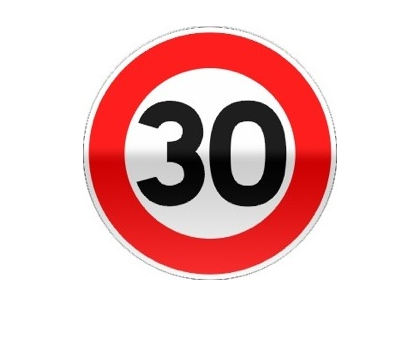

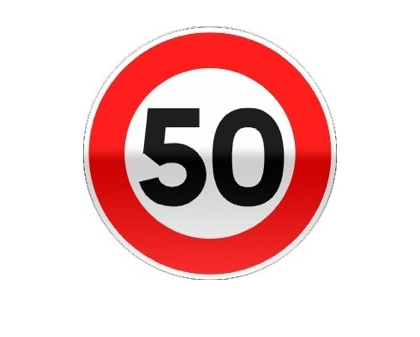

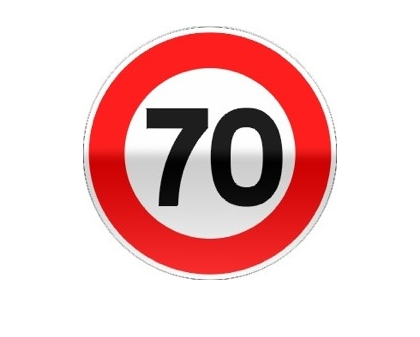

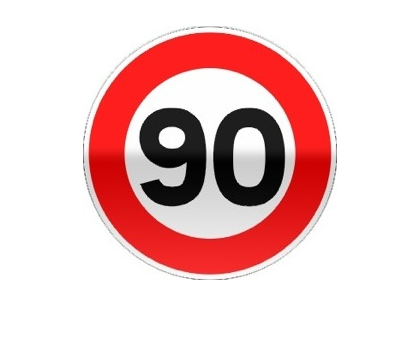

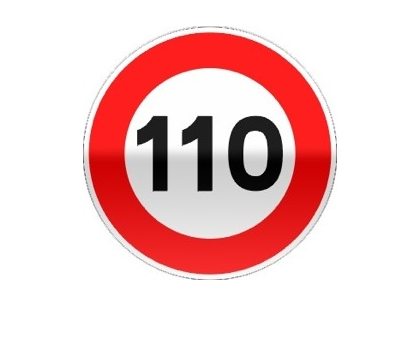


    ref = ['ref' num2str(10*i) '.jpg'];
    pan_ref_col = im2double(imread(ref));
    figure(10*i-1);
    imshow(pan_ref_col);

    pan_ref = rgb2gray(pan_ref_col);
    


## détection des features

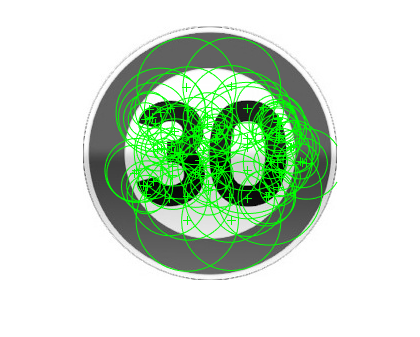

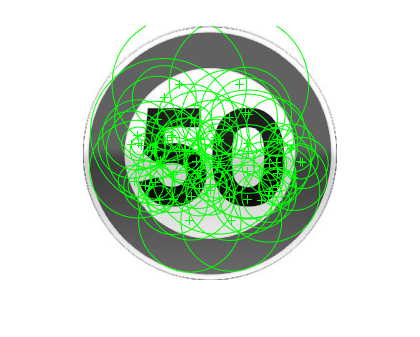

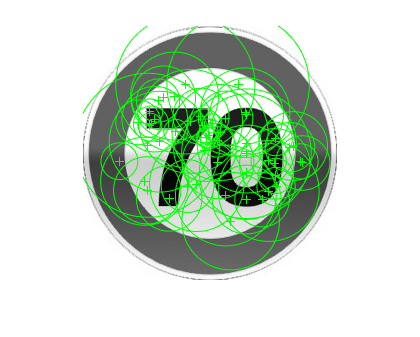

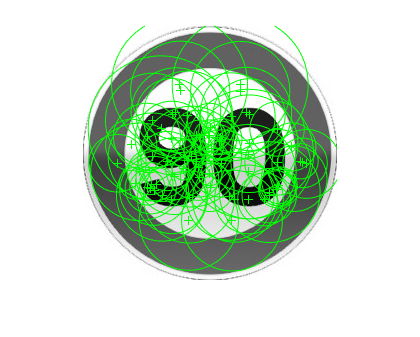

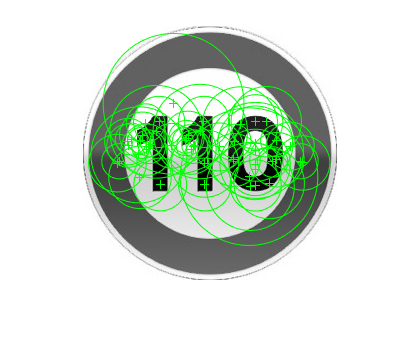

    points = detectSURFFeatures(pan_ref);
    figure(10*i)
    imshow(pan_ref);

    hold on;
    plot(points.selectStrongest(90));
    [features2, valid_points2] = extractFeatures(pan_ref,points,'Upright',true);


## stockage des features


    if i == 3
        struct_features_pan.ref30 = {features2, valid_points2,pan_ref_col};
    elseif i == 5
        struct_features_pan.ref50 = {features2, valid_points2,pan_ref_col};  
    elseif i == 7
        struct_features_pan.ref70 = {features2, valid_points2,pan_ref_col};
    elseif i == 9
        struct_features_pan.ref90 = {features2, valid_points2,pan_ref_col};
    elseif i == 11
        struct_features_pan.ref110 = {features2, valid_points2,pan_ref_col};
    end


## affichage des features

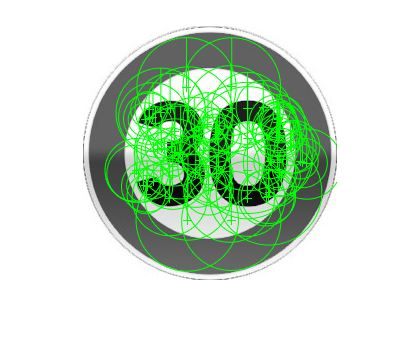

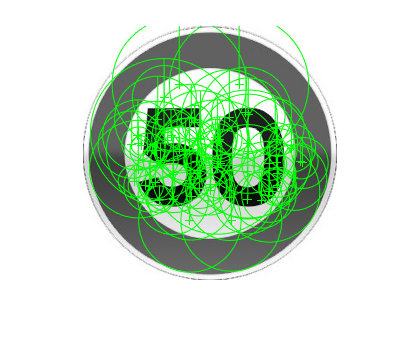

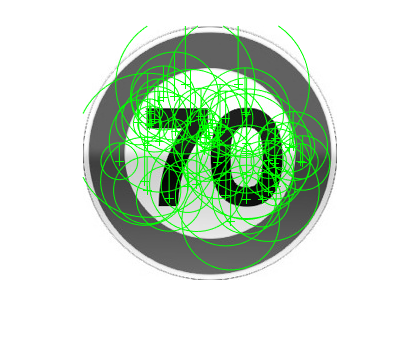

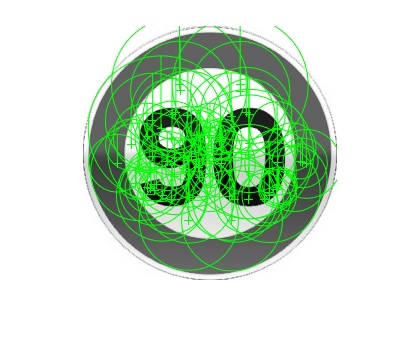

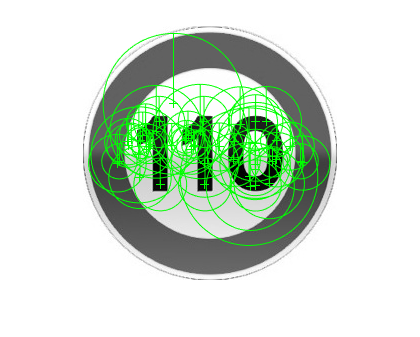

 
    figure(10*i+1)
    imshow(pan_ref); 

    hold on;
    plot(valid_points2,'showOrientation',true);
end

struct_features_pan

struct_features_pan = struct with fields:
     ref30: {[74×64 single]  [74×1 SURFPoints]  [254×254×3 double]}
     ref50: {[64×64 single]  [64×1 SURFPoints]  [254×254×3 double]}
     ref70: {[49×64 single]  [49×1 SURFPoints]  [254×254×3 double]}
     ref90: {[65×64 single]  [65×1 SURFPoints]  [254×254×3 double]}
    ref110: {[48×64 single]  [48×1 SURFPoints]  [254×254×3 double]}
